Copy_of_Lopez22212262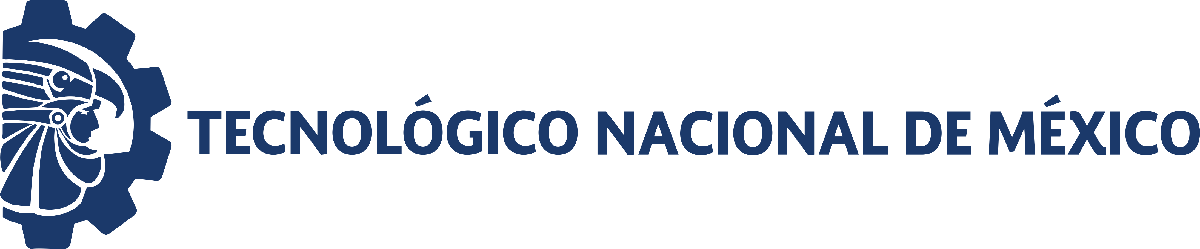                                 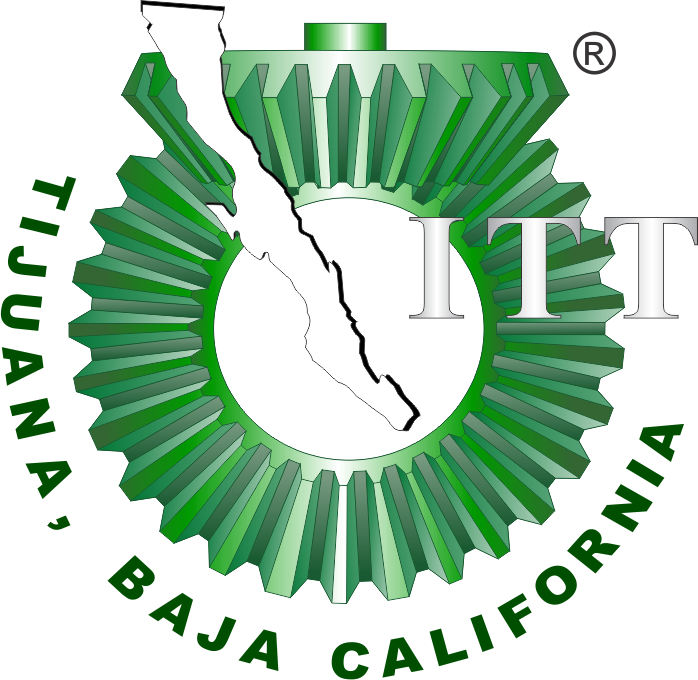

# Práctica DOS: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Copy_of_Lopez22212262Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: Antonio Lopez Reyes

Número de control: 22212262

Correo institucional:L22212262**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Copy_of_sistema';
open_system(file);
Signal = 'Pa(t)';
parameters.Stoptime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('Copy_of_sistema/Ppa(t)','Minimum','-0.2');
set_param('Copy_of_sistema/Ppa(t)','Maximum','1');
set_param('Copy_of_sistema/Ppa(t)','Seed','106');
set_param('Copy_of_sistema/Ppa(t)','SampleTime','0.5');
x= sim(file,parameters);
writematrix(x.Ppa,'Copy_of_sistema.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4)

## Respuesta al escalón

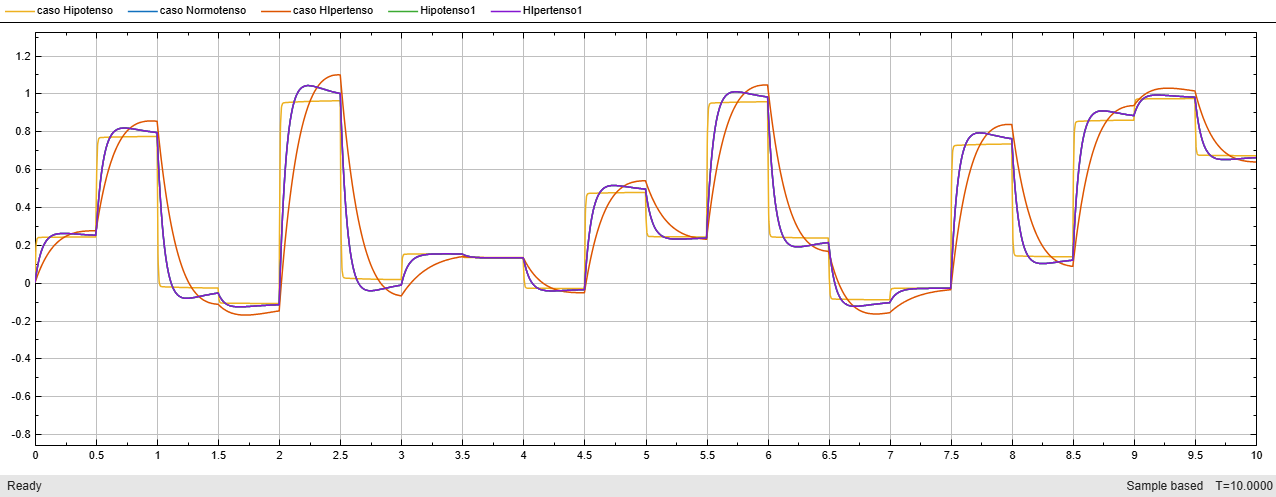

set_param('Copy_of_sistema/Ppa(t)','Minimum','-0.2');
set_param('Copy_of_sistema/Ppa(t)','Maximum','1');
set_param('Copy_of_sistema/Ppa(t)','Seed','106');
set_param('Copy_of_sistema/Ppa(t)','SampleTime','0.5');
x= sim(file,parameters);

plotsignals2(x.t,x.Pp0,x.Pp1,x.Pp2)

FUNCION: Respuesta a las señales

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4)
       set(figure(),'Color','w')
       set(gcf,'units','centimeters','position',[1,1,18,8])
       set(gca,'FontName','Times New Roman','Fontsize',11)
       hold on; grid off; box on;
       mycolors = [240,128,48;
                   15,130,140;
                   255,221,51;
                     204,0,34;
                   143,163,30;
                    107,36,12]/255;
       colororder(mycolors)

     

   p = plot(t,Pp0,'-',t,Pp1,'--o',t,Pp2,'--+',t,Pp3,'--x',t,Pp4,'--d',...
       'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
   set(p(5),'LineWidth',3);
   L = legend('$P_{p_0Normotenso}(t)$','$P_{p_1Hipotenso}(t)$','$P_{p_2Hipertenso}(t)$','$P_{p_3Hipotenso.PID}(t)$','$P_{p_4Hipertenso.PID}(t)$');
   set(L,'Interpreter','Latex','Fontsize',10,'Location','BestOutside','Box','On');
   title(L,["sistema cardio",' input'],'FontSize',10)

   xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
   ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11 )
    xlim([0,10]); xticks(0:1:10);

   exportgraphics(gcf,['sistema cardio', '.pdf'], 'ContentType','vector')
   exportgraphics(gcf,['sistema cardio', '.png'], 'ContentType','vector')

end

function plotsignals2(t,Pp0,Pp1,Pp2)
       set(figure(),'Color','w')
       set(gcf,'units','centimeters','position',[1,1,18,8])
       set(gca,'FontName','Times New Roman','Fontsize',11)
       hold on; grid off; box on;
       mycolors = [240,128,48;
                   15,130,140;
                   255,221,51]/255;
       colororder(mycolors)

   p = plot(t,Pp0,'-',t,Pp1,'--o',t,Pp2,'--+', ...
       'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
   set(p(3),'LineWidth',3);
   L = legend('$P_{p_0Normotenso}(t)$','$P_{p_1Hipotenso}(t)$','$P_{p_2Hipertenso}(t)$');
   set(L,'Interpreter','Latex','Fontsize',10,'Location','BestOutside','Box','On');
   title(L,["sistema cardio",' input'],'FontSize',10)

   xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
   ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11 )
   xlim([0,10]); xticks(0:1:10);


   exportgraphics(gcf,['sistema cardio Pi', '.pdf'], 'ContentType','vector')
   exportgraphics(gcf,['sistema cardio Pi', '.png'], 'ContentType','vector')

end




